## Deliverable 1

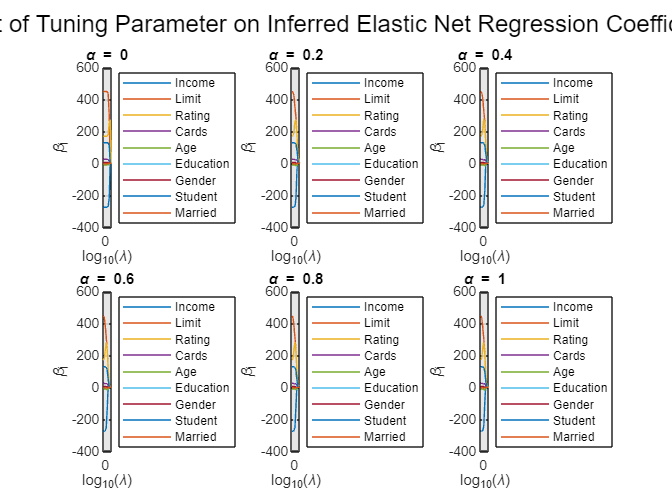

features = {'Income', 'Limit', 'Rating', 'Cards', 'Age', 'Education', 'Gender', 'Student', 'Married'};

figure;

for j = 1:length(alpha_values)
    alpha = alpha_values(j);
    
    % Subplot
    subplot(2, 3, j);
    
    for i = 1:p
        beta_j = squeeze(beta_hat(i, j, :));
        log_lambda = log10(lambda_values);
        
        plot(log_lambda, beta_j);
        hold on;
    end
    
    % Labels and title
    title(['\alpha = ', num2str(alpha)]);
    xlabel('log_{10}(\lambda)');
    ylabel('\beta_j');
    grid on;
    
    % Add feature names to the plot
    feature_names = features(1:p);  % Ensure it matches the number of features
    legend(feature_names, 'Location', 'eastoutside');
end

% Title
sgtitle('Effect of Tuning Parameter on Inferred Elastic Net Regression Coefficients');

## Deliverable 2

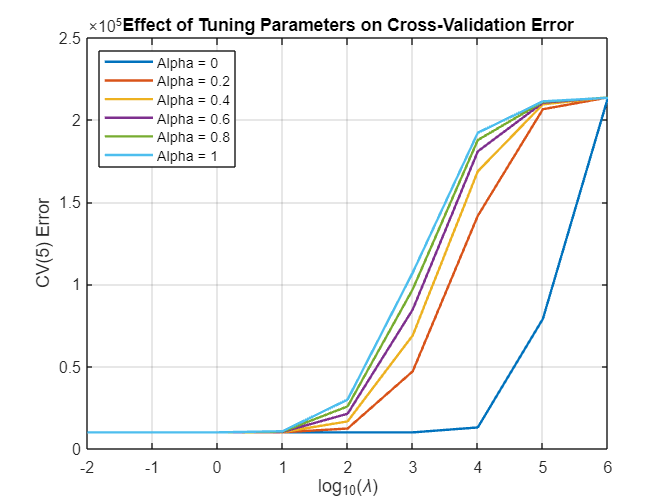

% Plot the effect of tuning parameters on cross-validation error

figure;
for alpha_idx = 1:length(alpha_values)
    plot(log10(lambda_values), avg_MSE(alpha_idx, :), 'LineWidth', 1.5, 'DisplayName', ['Alpha = ', num2str(alpha_values(alpha_idx))]);
    hold on;
end
xlabel('log_{10}(\lambda)');
ylabel('CV(5) Error');
title('Effect of Tuning Parameters on Cross-Validation Error');
legend('show', 'Location','northwest');
grid on;
hold off;

## Deliverables 3 & 4

% Deliverable 3: Indicate the pair of values 𝜆 and 𝛼 that generated the smallest CV(5) error.
% Deliverable 4: Given the optimal 𝜆 and 𝛼 pair, retrain your model on the entire dataset of 𝑁=400 
% observations and provide the estimates of the 𝑝=9 best-fit model parameters. How do these estimates 
% compare to the estimates obtained from ridge regression (𝛼=1 under optimal 𝜆 for 𝛼=1) and lasso 
% (𝛼=0 under optimal 𝜆 for 𝛼 =0) on the entire dataset of 𝑁=400 observations?

% Find the minimum CV error and corresponding alpha and lambda
[min_error, min_error_idx] = min(avg_MSE(:));
[min_alpha_idx, min_lambda_idx] = ind2sub(size(avg_MSE), min_error_idx);
best_alpha = alpha_values(min_alpha_idx);
best_lambda = lambda_values(min_lambda_idx);
fprintf('Best Alpha: %.6f\nBest Lambda: %.6f\nMin CV Error: %.6f\n', best_alpha, best_lambda, min_error);

Best Alpha: 0.000000
Best Lambda: 100.000000
Min CV Error: 9973.779342


fprintf('Best-fit Model Parameters Estimates:\n');

Best-fit Model Parameters Estimates:


for p = 1:length(beta_hat_optimal)
    fprintf('β_%d : %f\n', p, beta_hat_optimal(p));
end

β_1 : -274.398898
β_2 : 446.547310
β_3 : 169.071385
β_4 : 24.535358
β_5 : -10.855775
β_6 : -3.364527
β_7 : 5.064878
β_8 : 127.961056
β_9 : -3.304573


#### Lasso & Ridge Estimates

fprintf('Lasso & and Ridge Estimates:\n');

Lasso & and Ridge Estimates:


fprintf('Lasso (alpha = 1, lambda = %f) estimates:\n', best_lambda_lasso);

Lasso (alpha = 1, lambda = 0.010000) estimates:


for p = 1:length(beta_hat_optimal_lasso)
    fprintf('β_%d : %f\n', p, beta_hat_optimal_lasso(p));
end

β_1 : -274.948918
β_2 : 446.292630
β_3 : 169.889559
β_4 : 24.606137
β_5 : -10.949382
β_6 : -3.487518
β_7 : 5.205742
β_8 : 128.100879
β_9 : -3.419952


fprintf('Ridge (alpha = 0, lambda = %f) estimates:\n', best_lambda_ridge);

Ridge (alpha = 0, lambda = 0.010000) estimates:


for p = 1:length(beta_hat_optimal_ridge)
    fprintf('β_%d : %f\n', p, beta_hat_optimal_ridge(p));
end

β_1 : -274.981564
β_2 : 448.000820
β_3 : 168.211813
β_4 : 24.677792
β_5 : -10.944894
β_6 : -3.496822
β_7 : 5.206740
β_8 : 128.115259
β_9 : -3.407824


## Discussion

*How do these estimates compare to the estimates obtained from ridge regression (𝛼=1 under optimal 𝜆 for 𝛼=1) and lasso (𝛼=0 under optimal 𝜆 for 𝛼 =0) on the entire dataset of 𝑁=400 observations?*

- The Elastic Net estimates show some minor differences compared to both Lasso and Ridge. This is expected since Elastic Net is a combination of Lasso and Ridge regularization.

- The values of β_2 and β_3 are the most notable difference for Lasso and Ridge. The β_2 estimate for Elastic Net is closer to the β_2 for Lasso than Ridge.

Here are the one-to-one comparisons

- **Elastic Net (alpha = 0) and Lasso (alpha = 0)** estimates are quite similar, with only slight differences in some coefficients. Lasso tends to drive some coefficients to exactly zero, which is reflected in the differences observed.

- **Elastic Net (alpha = 0) and Ridge (alpha = 1)** estimates also show similarity, with small differences in some coefficients. Ridge regression applies a form of regularization that keeps all coefficients but shrinks them, which leads to these small variations.

- **Lasso (alpha = 0) and Ridge (alpha = 1)** estimates are different due to their regularization properties. Lasso tends to produce sparse solutions where some coefficients are exactly zero, while Ridge shrinks all coefficients but keeps them non-zero.